# Go to point with DSMR

**Authors:**

- Alejandro, Kenny

- Crespo, Nil

- Hossain,Tanvir

**Supervisor:**

- Martinez, Antonio Benito

## **1 Explanation** 

In this live script we are going to translate the "Go to point architecture of *sl_drivepoint *" made with simulink by Peter Corke into a secuential code using a DSMR.

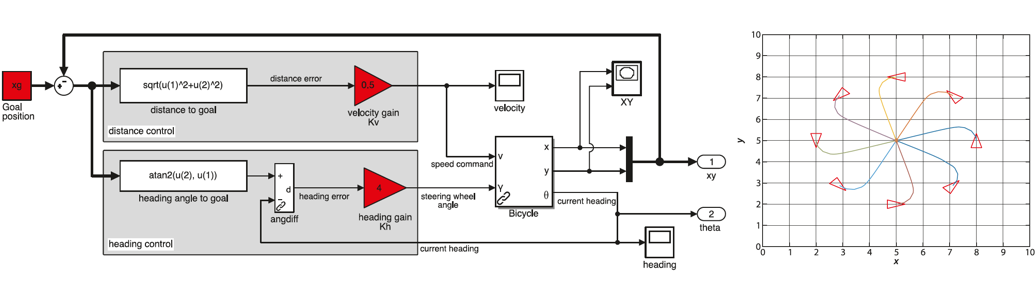

sl_drivepoint:

- It is express in simulink's language.

- Vehicle is a Bicycle.

Our version:

- It is a sequential code (using matlab's language).

- Vehicle is a DSMR(Differential Steering Mobile Robot).

## 2 Auxiliar functions

### **Invers Kinematics**

Find wheel's angular velocities from the velocity and steering


$$\left( {\begin{array}{*{20}{c}} {{{\dot \varphi }_r}} \\ {{{\dot \varphi }_l}} \end{array}} \right) =\frac{1}{r}\left( {\begin{array}{*{20}{c}} 1 \\  1 \end{array}} \right){}^{eR}{v_x} +\frac{1}{r} \left( {\begin{array}{*{20}{c}}  S \\ { - S} \end{array}} \right) \dot \psi 
= \frac{1}{r} \left[ {\begin{array}{*{20}{c}}
  {1&S \\ 
  {1&-S\\  
\end{array}} \right]
\left[ {\begin{array}{*{20}{c}}
  {{}^{eR}{v_x} }\\ 
  {\dot \psi }\\  
\end{array}} \right]$$
   

I_kine = @(v_x, psi,r,S) ...
[(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
w_s=I_kine(1,0,0.1,0.26)

w_s =     10    10


### Odometry

Based on Forward Kinematics (Find the displacement and steering increment from wheel's angular velocities) 


$$ \[\left( {\begin{array}{*{20}{c}}
  {{\delta _d}} \\ 
  {{\delta _\theta }} 
\end{array}} \right) = \frac{r}{{2S}}\left( {\begin{array}{*{20}{c}}
  S&S \\ 
  1&{ - 1} 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  \Delta\dot\varphi_r\ \\ 
  \Delta\dot\varphi_l  
\end{array}} \right) \Delta t$$


odo_vel = @(phi_r, phi_l,r,S,ts) ...
[(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
odo_vel(1,1,0.1,0.26,0.02)

ans =     0.0020         0


Odometry from cumulative


$$\Delta_r=R_k-R_{k-1}\\
\Delta_l=L_k-L_{k-1}$$



$$ \[\left( {\begin{array}{*{20}{c}}
  {{\delta _d}} \\ 
  {{\delta _\theta }} 
\end{array}} \right) = \frac{1}{{2S}}\left( {\begin{array}{*{20}{c}}
  S&S \\ 
  1&{ - 1} 
\end{array}} \right)\left( {\begin{array}{*{20}{c}}
  \Delta_r \\ 
   \Delta_l  
\end{array}} \right)\]$$


odo_cum = @(Delta_r, Delta_l,S) ...
[(1/2)*(Delta_r+Delta_l) (1/(2*S))*(Delta_r-Delta_l)];
odometry = odo_cum(-0.01,0.01,0.26)

odometry =          0   -0.0385


### Pose integration

$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCaebbnrfifHhDYfgasaacH8sr
% ps0lbbf9q8WrFfeuY-ribbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-
% yr0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dc9Gqpi0d
% meaabaqaciGacaGaaeqabaWaaeaaeaaakeaacqaH+oaEdaWgaaWcba
% Gaam4AaiabgUcaRiaaigdaaeqaaOGaeyypa0ZaaeWaaeaafaWabeGa
% baaabaGaamiCamaaBaaaleaacaWGRbGaey4kaSIaaGymaaqabaaake
% aacqaH4oqCdaWgaaWcbaGaam4AaiabgUcaRiaaigdaaeqaaaaaaOGa
% ayjkaiaawMcaaiabg2da9maabmaabaqbaeqabmqaaaqaaiaadIhada
% WgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWgaaWcbaGaamiE
% aaqabaGccaWGJbGaeqiYdK3aaSbaaSqaaiaadUgaaeqaaaGcbaGaam
% yEamaaBaaaleaacaWGRbaabeaakiabgUcaRiabes7aKnaaBaaaleaa
% caWG4baabeaakiaadohacqaHipqEdaWgaaWcbaGaam4Aaaqabaaake
% aacqaHipqEdaWgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWg
% aaWcbaGaeqiYdKhabeaaaaaakiaawIcacaGLPaaaaaa!5E74!
\[{\xi _{k + 1}} = \left( {\begin{array}{*{20}{c}}
  {{p_{k + 1}}} \\ 
  {{\theta _{k + 1}}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {{x_k} + {\delta _x}c{\psi _k}} \\ 
  {{y_k} + {\delta _x}s{\psi _k}} \\ 
  {{\psi _k} + {\delta _\psi }} 
\end{array}} \right)\]$, keep in mind that $\theta_{k+1}$ goes from 0 to $2\pi$ 

Pose_int=@(X_ant,odo) ...
[X_ant(1)+odo(1)*cos(X_ant(3)) ...
 X_ant(2)+odo(1)*sin(X_ant(3)) ...
 X_ant(3)+odo(2)];
Next_pose=Pose_int([0 0 0],odometry)

Next_pose =          0         0   -0.0385


## **3 GoTo Point Implementation**

Before executing this section reproduce the previous secction "Auxiliar functions"

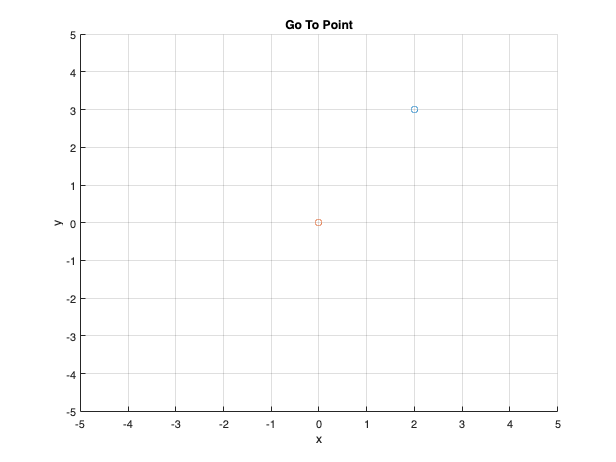

startPose = [0,0,-pi]; % startPose [x y theta] 
goal = [2,3]; % goal position

Kv = 0.9; % Velocity Gain. Units (m/s)/m = [1/s]
Kh = 4; % Head Gain. Units [1/s]
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;
figure
scatter(goal(1),goal(2));
hold on
scatter(startPose(1),startPose(2));
xlabel('x');
ylabel('y');
title('Go To Point')
grid
axis([-5 5 -5 5])
xticks(-5:5);
yticks(-5:5);

## Robot shape

Robot.V= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Robot = struct with fields:
    V: [3×4 double]
    F: [1 2 3]


Robot.F = [1,2,3];
hr=[];

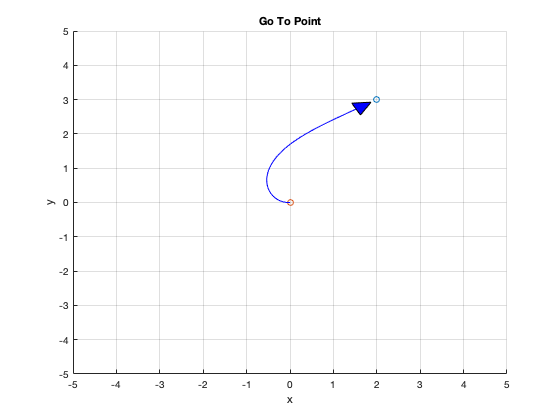

hold on
axis([-5 5 -5 5])
while (~stop)
    delete (hr);
    currentdiff = goal - currentPose([1,2]);
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2); 
    if throttle < 0.1 %we can stop if distance error is less than 0.1
        stop = true;
    else
        velocity = throttle *  Kv;
        steering = atan2(currentdiff(2),currentdiff(1));
        psi = angdiff(steering,currentPose(3))*Kh;
        phi_l_r = I_kine(velocity,psi,r,S);
        deltas = odo_vel(phi_l_r(1),phi_l_r(2),r,S,ts);
        lastPose = currentPose;
        currentPose = Pose_int(currentPose,[deltas(1),deltas(2)]);
        pose = transl(currentPose(1),currentPose(2),0)* trotz(currentPose(3));
        Robot_tr=pose*Robot.V';% moving the robot 
        hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b'); 
        pause(0.05);
        plot([lastPose(1),currentPose(1)],[lastPose(2),currentPose(2)],...
        'LineStyle',"-","Color",'blue');
    end
end
legend('goalPoint','startPoint','path');

We encapsulate the algoritm in a function called  **goToPoint(goal,startPose,Kv,Kh,minStopDistance), **which returns all the trajectory poses that are needed to go from the given startPose (position and orientation) to a less than a minStopDistance of the goal point.

## **4 Go To Point Applications**

Implementation of the application persuit arquitecture of motion control: a collection of sucessives nearby point

Use the function 'frontend.m' to trace a path. Get familiar with its use.

We nee to encapsulate the gotopoint idea into a function.

We will base this function into the anonymous function introduced above. (I_kine, odo_vel and Pose_int)